# **Power calculations of Stirling Engine**

To maximise the efficiency of our stirling engine we have chosen the **Beta-Rhombic Configuration.**

We made a model on** Linkages**, in order to model the volume changes accurately and visualise the motion. From there we exported the motion paths into a CSV file that was then used by our MATLAB code.

Assumptions:

- The working fluid is an ideal gas

- The Pressure is uniform throughout the working fluid

- Temperatute of the working fluid in the hot region is T_h, and that in the cold region is T_c

Calculations:

The displacer piston divided the working fluid into hot and cold regions. We have obtained Vhot and Vcold from Linkages motion paths.

Vnet= Vhot + Vcold + Vregenerator

P = mRT / V            -- *ideal gas equation*

P=mRTh / Vh          -- *hot region (1)*

P=mRTh / Vh          -- *cold region (2)*

P=mR(Th-Tc) / log(Th/Tc)Vr  -- *regenerator region (assuming linear temperature gradient) (3)*

The net pressure is the sum of all these contributions.

Plotting and Analysis

Using P and Vnet we plot the P-V curve for the stirling engine. Work output is the area enclosed by the curve. Heat is the area under the expansion curve. Hence we find efficiency and compare it with the carnott efficiency.

crank_angle=linspace(0,2*pi,200);
phase_angle=pi/2;
array=ones(1,121);

%volumes of dea hot, cold, swept max and regenerator
A=50;
d=1; %dead volume
V_r=1

V_r = 1


% Temperatures
t_h=300

t_h = 300

t_c=100

t_c = 100

T_h=t_h*array;
T_c=t_c*array;
t=T_h/T_c

t = 3.0000


%Crank and Coupler lengths- Linkages file

%working fluid Characteristics
m=1*array;
R=8*array;

% Volume Calculations: importing data from motion paths
data=csvread("Beta_rhombic_drive.csv",2,0);
C_y_raw=data(:,2)';
K_y_raw=data(:,8)';
    
C_y=C_y_raw(1:121); %taking data of one rotation
K_y=K_y_raw(1:121);
    
L=max(C_y)-min(C_y);
V_hot=A*(L+d -C_y);
V_cold=A*(C_y-K_y);

V_net= V_cold+V_hot+V_r; %total volume of working fluid
Pressure=arrayfun(@Pressure,m,R,T_c,T_h,V_cold,V_hot,V_r*array);

%plotting
plot(V_net,Pressure)
hold on
work_net=polyarea(V_net,Pressure)

work_net = 64.4769

mean_pressure=mean(Pressure)

mean_pressure = 0.4402

plot(V_net,mean_pressure*array)
hold on
%Heat Calculations: (work done in expansion)
V_min=min(V_net);
V_max=max(V_net);
index_min=find(V_net==V_min); %finding range when expansion occurs
index_max=find(V_net==V_max);

plot([V_min V_net(index_min:index_max) V_max],[0 Pressure(index_min:index_max) 0])
area([V_min V_net(index_min:index_max) V_max],[0 Pressure(index_min:index_max) 0])
heat=polyarea([V_min V_net(index_min:index_max) V_max],[0 Pressure(index_min:index_max) 0])

heat = 344.7112

area([V_max V_net(index_max:121) V_net(1:index_min) V_min],[0 Pressure(index_max:121) Pressure(1:index_min) 0])
%energy_lost=polyarea([V_max V_net(index_max:121) V_net(1:index_min) V_min],[0 Pressure(index_max:121) Pressure(1:index_min) 0])
%efficiency1=1-energy_lost/heat
efficiency=work_net/heat

efficiency = 0.1870

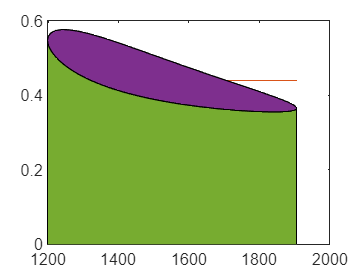

hold off